% Need to run LoadRawData.m
% LoadRawData();
% Need to run preprocessData.mlx
% preprocessData();

numOfPulses = 0;
for i=1:size(pulseData_FunctionOutput, 2)
    numOfPulses = numOfPulses + (size(pulseData_FunctionOutput{i}, 2));
end

totalPulses = 1;
clearanceData = [numOfPulses, 12]; % 1
crestData = [numOfPulses, 12]; % 2
impulseData = [numOfPulses, 12]; % 3
kurtosisData = [numOfPulses, 12]; %4
meanData = [numOfPulses, 12]; % 5
peakData = [numOfPulses, 12]; % 6
rmsData = [numOfPulses, 12]; % 7
%SNR % 8
%SINAD % 9
shapeData = [numOfPulses, 12]; %10
skewnessData = [numOfPulses, 12]; %11
stdData = [numOfPulses, 12]; % 12 
%thdData % 13

for fileIndex = 1:size(pulseData_FunctionOutput, 2)
    for pulseIndex = 1:size(pulseData_FunctionOutput{fileIndex}, 2)
        for sensorIndex = 1:size(pulseData_FunctionOutput{fileIndex}{pulseIndex}, 2)
            pulse = pulseData_FunctionOutput{fileIndex}{pulseIndex}(:, sensorIndex);

            clearanceData(totalPulses, sensorIndex) = fnClearanceFactor(pulse);
            crestData(totalPulses, sensorIndex) = fnCrestFactor(pulse);
            impulseData(totalPulses, sensorIndex) = fnImpulseFactor(pulse);            
            kurtosisData(totalPulses, sensorIndex) = fnKurtosis(pulse);
            meanData(totalPulses, sensorIndex) = mean(pulse);
            peakData(totalPulses, sensorIndex) = max(pulse);
            rmsData(totalPulses, sensorIndex) = fnRMS(pulse);
            shapeData(totalPulses, sensorIndex) = fnShapeFactor(pulse);
            skewnessData(totalPulses, sensorIndex) = fnSkewness(pulse);
            stdData(totalPulses, sensorIndex) = std(pulse);            
        end
        totalPulses = totalPulses + 1;
    end
end

## 1. Clearance Factor

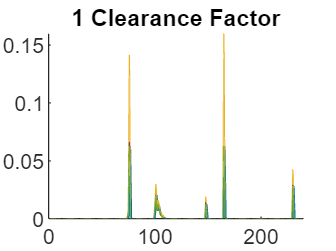

% Clearance Factor
figure(); hold on;
title("1 Clearance Factor");
for sensorIndex=1:size(clearanceData, 2)
    plot(clearanceData(:, sensorIndex));
end

## 2. Crest Factor

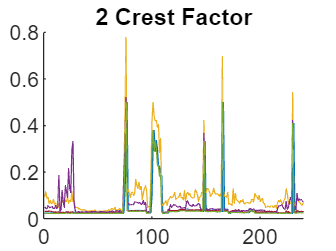

% Crest Factor
figure(); hold on;
title("2 Crest Factor");
for sensorIndex=1:size(crestData, 2)
    plot(crestData(:, sensorIndex));
end

## 3. Impulse Factor

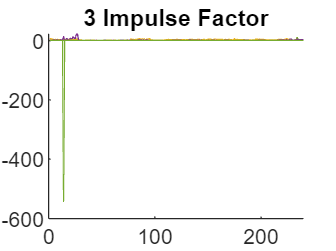

% Impulse Factor
figure(); hold on;
title("3 Impulse Factor");
for sensorIndex=1:size(impulseData, 2)
    plot(impulseData(:, sensorIndex));
end

## 3. Shape Factor

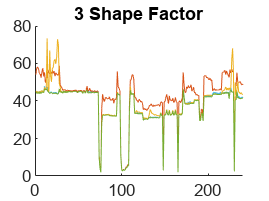

% Shape Factor
figure(); hold on;
title("3 Shape Factor");
for sensorIndex=1:size(rmsData, 2)
    plot(shapeData(:, sensorIndex));
end

## 4. Kurtosis

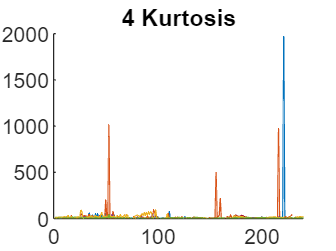

% quantifies the peak value of the PDF. 
% The kurtosis value for normal rolling element bearing is well-recognized as 3.
figure(); hold on;
title("4 Kurtosis");
for sensorIndex=1:size(kurtosisData, 2)
    plot(kurtosisData(:, sensorIndex));
end

## 5. Mean

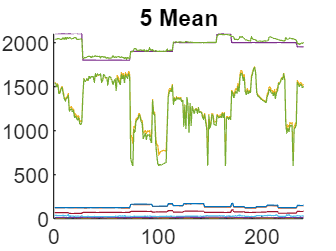

% Mean
figure(); hold on;
title("5 Mean");
for sensorIndex=1:size(meanData, 2)
    plot(meanData(:, sensorIndex));
end

## 6. Peak Value

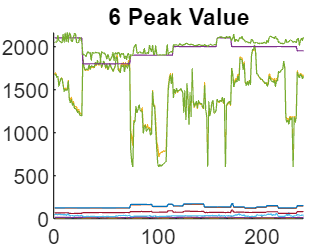

% Peak Value
figure(); hold on;
title("6 Peak Value");
for sensorIndex=1:size(peakData, 2)
    plot(peakData(:, sensorIndex));
end

## 7. RMS

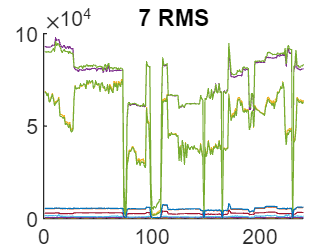

% RMS
figure(); hold on;
title("7 RMS");
for sensorIndex=1:size(rmsData, 2)
    plot(rmsData(:, sensorIndex));
end

## 8. SNR

% SNR

## 9. SINAD

% SINAD

## 10. Shape Factor

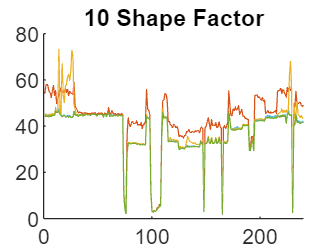

% Shape Factor
figure(); hold on;
title("10 Shape Factor");
for sensorIndex=1:size(shapeData, 2)
    plot(shapeData(:, sensorIndex));
end

## 11. Skewness

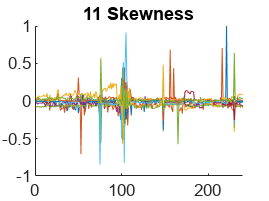

% Skewness quantifies the asymmetry behavior of vibration signal through its
% probability density function (PDF).
figure(); hold on;
title("11 Skewness");
for sensorIndex=1:size(skewnessData, 2)
    plot(skewnessData(:, sensorIndex));
end

## 12. STD

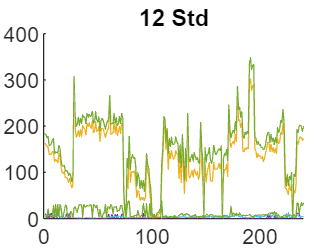

% STD
figure(); hold on;
title("12 Std");
for sensorIndex=1:size(stdData, 2)
    plot(stdData(:, sensorIndex));
end

## 13. THD

% THD